###  Завантаження тестових зображень

clc;
clear;
close all;

% Завантаження кількох зображень з бібліотеки MATLAB та власні зображення
I1 = imread('cameraman.tif');
I2 = imread('Imageslab2/hero.jpg');
I3 = imread('Imageslab2/mask.jpg'); 

Перетворення кольорових зображень у grayscale

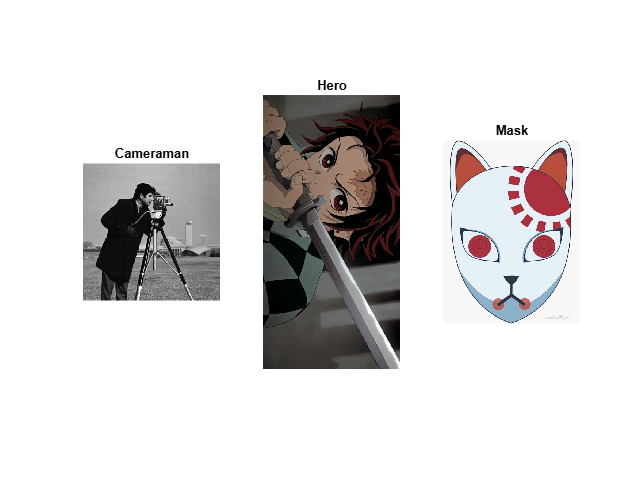

if size(I2,3) == 3
    I2_gs = rgb2gray(I2);
else
    I2_gs = I2;
end

if size(I3,3) == 3
    I3_gs = rgb2gray(I3);
else
    I3_gs = I3;
end
figure;
subplot(1,3,1), imshow(I1), title('Cameraman');
subplot(1,3,2), imshow(I2), title('Hero');
subplot(1,3,3), imshow(I3), title('Mask');

### Додавання шумів

% Додавання шумів
I1_gauss = imnoise(I1, 'gaussian', 0, 0.01);
I2_gauss = imnoise(I2_gs, 'gaussian', 0, 0.01); 
I3_gauss = imnoise(I3_gs, 'gaussian', 0, 0.01);

I1_sp = imnoise(I1, 'salt & pepper', 0.02);
I2_sp = imnoise(I2_gs, 'salt & pepper', 0.1);   
I3_sp = imnoise(I3_gs, 'salt & pepper', 0.01);

Відображення зашумлених зображень

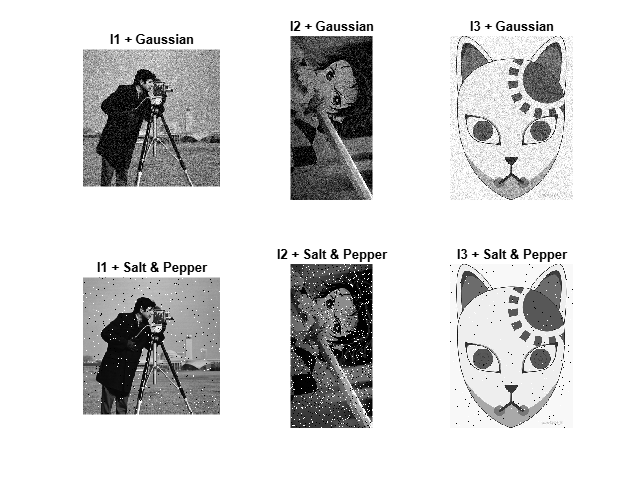

figure;
subplot(2,3,1), imshow(I1_gauss), title('I1 + Gaussian');
subplot(2,3,2), imshow(I2_gauss), title('I2 + Gaussian');
subplot(2,3,3), imshow(I3_gauss), title('I3 + Gaussian');
subplot(2,3,4), imshow(I1_sp), title('I1 + Salt & Pepper');
subplot(2,3,5), imshow(I2_sp), title('I2 + Salt & Pepper');
subplot(2,3,6), imshow(I3_sp), title('I3 + Salt & Pepper');

###  Фільтрація лінійними фільтрами (високі/низькі частоти)

h_low = fspecial('average', [3 3]);
h_high = fspecial('laplacian');
% Фільтр низьких частот (розмиття)
I1_low = imfilter(I1, h_low);
I2_low = imfilter(I2, h_low);
I3_low = imfilter(I3, h_low);
% Фільтр високих частот (виявлення країв)
I1_high = imfilter(I1, h_high);
I2_high = imfilter(I2, h_high);
I3_high = imfilter(I3, h_high);


 Відображення результатів фільтрації

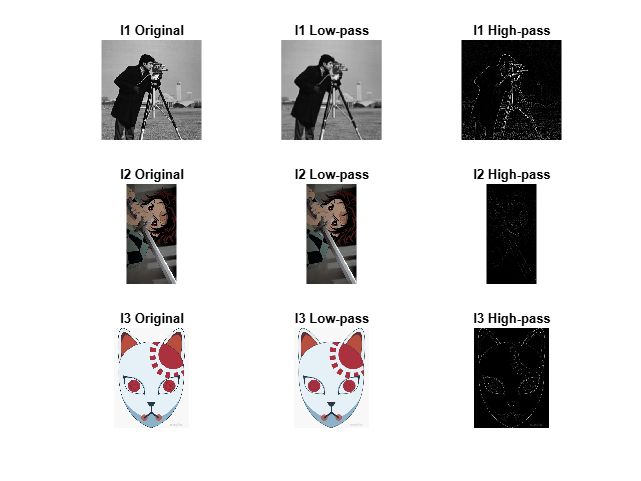

figure;
subplot(3,3,1), imshow(I1), title('I1 Original');
subplot(3,3,2), imshow(I1_low), title('I1 Low-pass');
subplot(3,3,3), imshow(I1_high, []), title('I1 High-pass');

subplot(3,3,4), imshow(I2), title('I2 Original');
subplot(3,3,5), imshow(I2_low), title('I2 Low-pass');
subplot(3,3,6), imshow(I2_high, []), title('I2 High-pass');

subplot(3,3,7), imshow(I3), title('I3 Original');
subplot(3,3,8), imshow(I3_low), title('I3 Low-pass');
subplot(3,3,9), imshow(I3_high, []), title('I3 High-pass');

### Фільтрація зашумлених зображень лінійними фільтрами

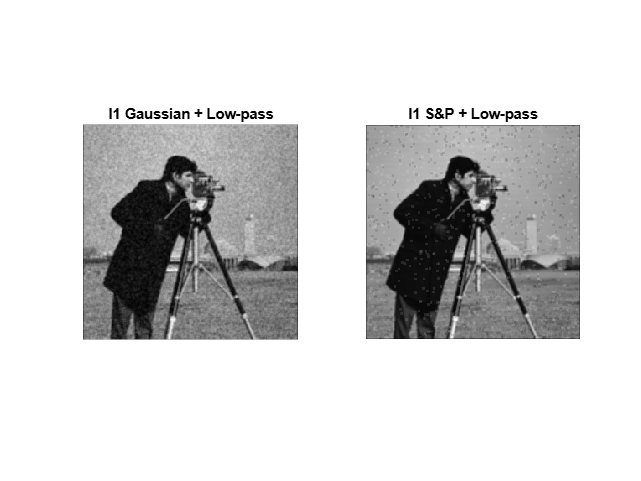

% Застосування до зашумлених зображень
figure;
subplot(1,2,1), imshow(imfilter(I1_gauss, h_low)), title('I1 Gaussian + Low-pass');
subplot(1,2,2), imshow(imfilter(I1_sp, h_low)), title('I1 S&P + Low-pass');

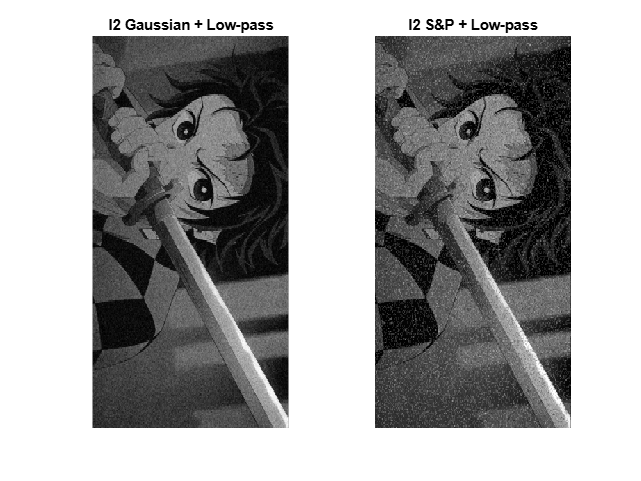


figure;
subplot(1,2,1), imshow(imfilter(I2_gauss, h_low)), title('I2 Gaussian + Low-pass');
subplot(1,2,2), imshow(imfilter(I2_sp, h_low)), title('I2 S&P + Low-pass');

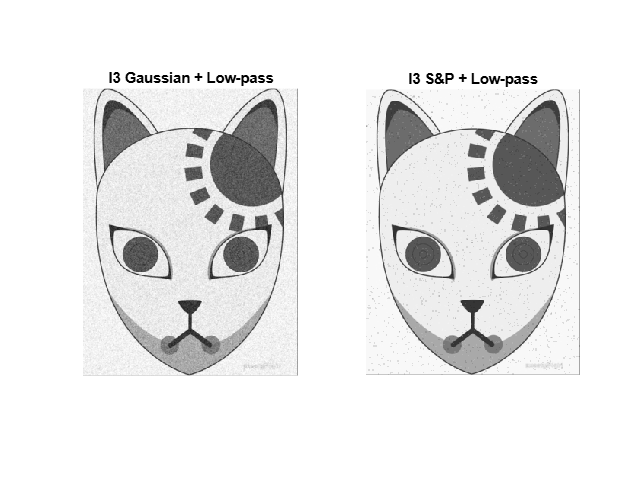


figure;
subplot(1,2,1), imshow(imfilter(I3_gauss, h_low)), title('I3 Gaussian + Low-pass');
subplot(1,2,2), imshow(imfilter(I3_sp, h_low)), title('I3 S&P + Low-pass');

###  Адаптивна вінерівська фільтрація

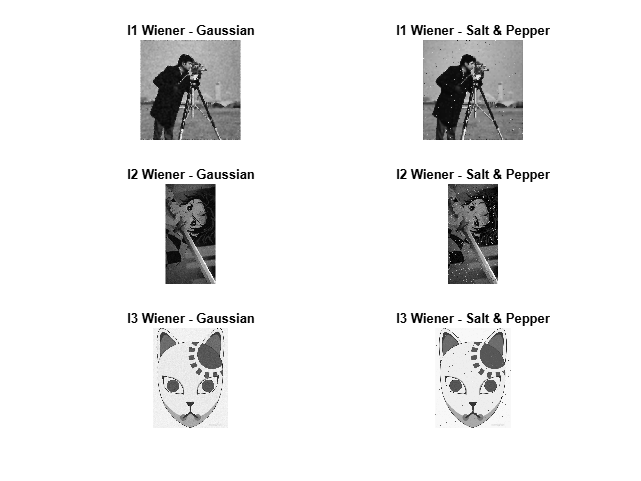

% Вінерівська фільтрація
wiener_gauss1 = wiener2(I1_gauss, [5 5]);
wiener_sp1 = wiener2(I1_sp, [5 5]);

wiener_gauss2 = wiener2(I2_gauss, [5 5]);
wiener_sp2 = wiener2(I2_sp, [5 5]);

wiener_gauss3 = wiener2(I3_gauss, [5 5]);
wiener_sp3 = wiener2(I3_sp, [5 5]);

figure;
subplot(3,2,1), imshow(wiener_gauss1), title('I1 Wiener - Gaussian');
subplot(3,2,2), imshow(wiener_sp1), title('I1 Wiener - Salt & Pepper');
subplot(3,2,3), imshow(wiener_gauss2), title('I2 Wiener - Gaussian');
subplot(3,2,4), imshow(wiener_sp2), title('I2 Wiener - Salt & Pepper');
subplot(3,2,5), imshow(wiener_gauss3), title('I3 Wiener - Gaussian');
subplot(3,2,6), imshow(wiener_sp3), title('I3 Wiener - Salt & Pepper');

###  Нелінійна медіанна фільтрація

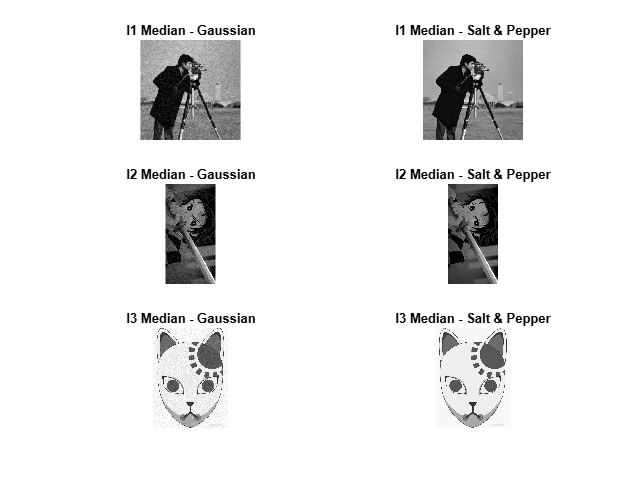

% Медіанна фільтрація
med_gauss = medfilt2(I1_gauss, [3 3]);
med_gauss1 = medfilt2(I1_gauss, [3 3]);
med_sp1 = medfilt2(I1_sp, [3 3]);

med_gauss2 = medfilt2(I2_gauss, [3 3]);
med_sp2 = medfilt2(I2_sp, [3 3]);

med_gauss3 = medfilt2(I3_gauss, [3 3]);
med_sp3 = medfilt2(I3_sp, [3 3]);

figure;
subplot(3,2,1), imshow(med_gauss1), title('I1 Median - Gaussian');
subplot(3,2,2), imshow(med_sp1), title('I1 Median - Salt & Pepper');
subplot(3,2,3), imshow(med_gauss2), title('I2 Median - Gaussian');
subplot(3,2,4), imshow(med_sp2), title('I2 Median - Salt & Pepper');
subplot(3,2,5), imshow(med_gauss3), title('I3 Median - Gaussian');
subplot(3,2,6), imshow(med_sp3), title('I3 Median - Salt & Pepper');